clc
clear all
close all

# Reinforcement learning

## Evironement demo

Open class template for reinforcement learning environement

% % rlCreateEnvTemplate("MyEnvironment")

Validate environement

% env = classM3C;
% validateEnvironment(env)

Test environement

% env = classM3C
% reset(env);
% 
% T = 0.5;
% tic
% for i = 1:round(T/env.Tl)
%     [O, R, IsDone, info] = step(env, ones(5, 1));
% end
% toc
% plot(env)

## Instantiate environement

env = classM3C

env =   classM3C with properties:

                    Tf: 0.5000
                    Ts: 2.0000e-05
                    Ti: 2.0000e-04
                Ti_idx: 10
                    Tl: 1.0000e-04
                Tl_idx: 5
                    Ax: 7000
                   fxi: 50
                   wx0: 314.1593
                    Ay: 5000
                   fyi: 30
                   wy0: 188.4956
                     A: [6×9 double]
                 pinvA: [9×6 double]
                     m: 9
                     N: [9×4 double]
                 pinvN: [4×9 double]
                     C: 0.0200
                     L: 0.0200
                     R: 1.0000e-03
               Tabc_ab: [2×3 double]
               Tab_abc: [3×2 double]
      Tabc_dq_function: @(g)(2/3)*[cos(g),cos(g-2*pi/3),cos(g+2*pi/3);-sin(g),-sin(g-2*pi/3),-sin(g+2*pi/3)]
               Vxy_max: 12000
               Von_max: 6000
                I

InitialObservation = reset(env)

InitialObservation = 1.0e+05 *

    8.1123
    8.2177
    7.8872
    8.1386
    8.0946
    7.9634
    8.0338
    8.0965
    8.3607
         0



obsInfo = env.getObservationInfo

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "ICB+LFOM Inputs"
    Description: "Ec (9), vB (9), iB (9)"
      Dimension: [27 1]
       DataType: "double"

actInfo = env.getActionInfo

actInfo =   rlNumericSpec with properties:

     LowerLimit: [5×1 double]
     UpperLimit: [5×1 double]
           Name: "ICB+LFOM Outputs"
    Description: "ie (4), von (1)"
      Dimension: [5 1]
       DataType: "double"

## Critic

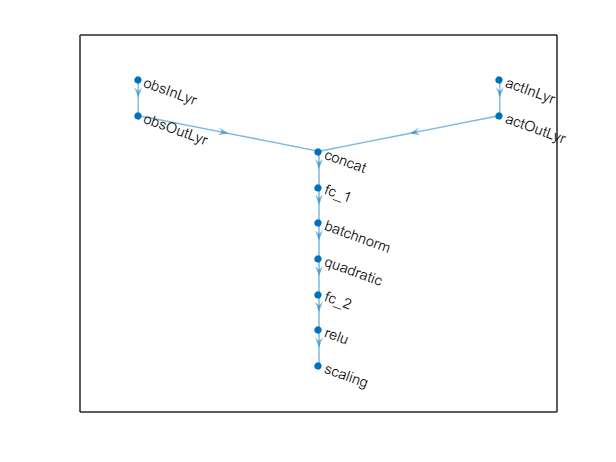

% Observation, action and concatenation paths
obsPath = [featureInputLayer(obsInfo.Dimension(1), 'Name', 'obsInLyr')
           fullyConnectedLayer(obsInfo.Dimension(1), 'Name', 'obsOutLyr', 'WeightsInitializer', 'narrow-normal', 'BiasInitializer', 'narrow-normal')
           ];

actPath = [featureInputLayer(actInfo.Dimension(1), 'Name', 'actInLyr')
           fullyConnectedLayer(actInfo.Dimension(1), 'Name','actOutLyr', 'WeightsInitializer', 'narrow-normal', 'BiasInitializer', 'narrow-normal')
           ];

commonPath = [
    concatenationLayer(1, 2, Name="concat")
    fullyConnectedLayer(obsInfo.Dimension(1)+actInfo.Dimension(1), 'WeightsInitializer', 'narrow-normal', 'BiasInitializer', 'narrow-normal')
    batchNormalizationLayer
    quadraticLayer
    fullyConnectedLayer(1, 'WeightsInitializer', 'narrow-normal', BiasLearnRateFactor=0, Bias=0)
    reluLayer
    scalingLayer('Scale', -1)
    ];

criticNet = dlnetwork;
criticNet = addLayers(criticNet, obsPath);
criticNet = addLayers(criticNet, actPath);
criticNet = addLayers(criticNet, commonPath);
criticNet = connectLayers(criticNet, "obsOutLyr", "concat/in1");
criticNet = connectLayers(criticNet, "actOutLyr", "concat/in2");
figure
plot(criticNet)

criticNet = initialize(criticNet);
summary(criticNet)

   Initialized: true
   Number of learnables: 2.4k
   Inputs:
      1   'obsInLyr'   27 features
      2   'actInLyr'   5 features


critic = rlQValueFunction(criticNet, obsInfo, actInfo, ...
                          ObservationInputNames="obsInLyr", ...
                          ActionInputNames="actInLyr");
getValue(critic, {rand(obsInfo.Dimension)}, {rand(actInfo.Dimension)})

ans = single
0

## Actor

actorLayers = [
                % Input
                featureInputLayer(obsInfo.Dimension(1), 'Name', 'actorInLyr', 'Normalization', @(X) X ./ Xmax)
                % Fully connected 1
                fullyConnectedLayer(obsInfo.Dimension(1), 'Name', 'FC1', 'WeightsInitializer', 'narrow-normal')
                batchNormalizationLayer
                geluLayer
                % Fully connected 2
                fullyConnectedLayer(obsInfo.Dimension(1), 'Name', 'FC2', 'WeightsInitializer', 'narrow-normal')
                batchNormalizationLayer
                geluLayer
                % Residual conection
                additionLayer(2, 'Name', 'additionLayer')
                % Fully connected 3
                fullyConnectedLayer(actInfo.Dimension(1), 'Name', 'FC3', 'WeightsInitializer', 'narrow-normal')
                tanhLayer
                scalingLayer('Scale', Ymax)
                ];

Unrecognized function or variable 'Ymax'.


actorNet = dlnetwork;
actorNet = addLayers(actorNet, actorLayers);
% actorNet = connectLayers(actorNet, 'FC2', 'additionLayer/in1');
actorNet = connectLayers(actorNet, 'actorInLyr', 'additionLayer/in2');

actorNet = dlupdate(@double, actorNet);


% NNgenerator_args = struct();
% NNgenerator_args.Ninputs = obsInfo.Dimension(1); %Ninputs;
% NNgenerator_args.Noutputs = actInfo.Dimension(1); %Noutputs;
% NNgenerator_args.NFFlayers = 3;
% NNgenerator_args.NRlayers = 0;
% NNgenerator_args.NFFneurons = obsInfo.Dimension(1); %Ninputs;
% NNgenerator_args.Nwindow = 1;
% NNgenerator_args.hidden_activation = 'geluLayer';
% NNgenerator_args.output_activation = 'tanhLayer';
% NNgenerator_args.dropout = 0;
% NNgenerator_args.WinitFcn = 'narrow-normal';
% NNgenerator_args.BinitFcn = 'narrow-normal';
% NNgenerator_args.train_bias = false;
% NNgenerator_args.scale_data = true;
% NNgenerator_args.Xmax = env.Xmax;
% NNgenerator_args.Ymax = env.Ymax
% 
% actorNet = NNgenerator(NNgenerator_args)
% actorNet = dlupdate(@double, actorNet);

figure
plot(actorNet)
actorNet = initialize(actorNet);
summary(actorNet)
actor = rlContinuousDeterministicActor(actorNet, obsInfo, actInfo);
cell2mat(getAction(actor, {rand(obsInfo.Dimension)}))

## Agent

agent = rlDDPGAgent(actor, critic);
agent.AgentOptions.SampleTime = env.Tl;
agent.AgentOptions.DiscountFactor = 0.99;
agent.AgentOptions.NoiseOptions.Mean = 0;
agent.AgentOptions.NoiseOptions.StandardDeviation = 0;
agent.AgentOptions.NoiseOptions.StandardDeviationDecayRate = 1e-5;
agent.AgentOptions.ExperienceBufferLength = 1e5;
agent.AgentOptions.MiniBatchSize = 256;
agent.AgentOptions.SequenceLength = 1;
agent.AgentOptions.ActorOptimizerOptions.LearnRate = 1e-3;
agent.AgentOptions.ActorOptimizerOptions.GradientThreshold = 1;
agent.AgentOptions.CriticOptimizerOptions.LearnRate = 5e-3;
agent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;
agent.AgentOptions.NumStepsToLookAhead = 1;
agent.AgentOptions.NumWarmStartSteps = agent.AgentOptions.MiniBatchSize;
agent.AgentOptions.NumEpoch = 1;
agent.AgentOptions.MaxMiniBatchPerEpoch = 100;
agent.AgentOptions.LearningFrequency = -1;
agent.AgentOptions.PolicyUpdateFrequency = 1;
agent.AgentOptions.TargetSmoothFactor = 1.0000e-03;
agent.AgentOptions.TargetUpdateFrequency = 1;
agent.AgentOptions.BatchDataRegularizerOptions = [];
agent.AgentOptions.ResetExperienceBufferBeforeTraining = 0;

## Train

trainOpts = rlTrainingOptions(...
    MaxEpisodes=1000, ...
    MaxStepsPerEpisode=ceil(env.Tf/env.Tl), ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    ScoreAveragingWindowLength=5,...
    StopTrainingValue=0);

doTraining = true;
if doTraining
    trainingStats = train(agent, env, trainOpts);
end
actual_agent = agent

## Test trained agent

% % env = classM3C;
% obs = reset(env);
% T = 0.1;
% tic
% for i = 1:round(T/env.Tl)
%     action = cell2mat(getAction(actual_agent, {obs}));
%     [obs, reward, isDone, info] = step(env, action);
% end
% toc

% env.PlotLastN = 100000
% plot(env)
% % close all
% % env.UpdatePlot = false;
% env.CC.vs